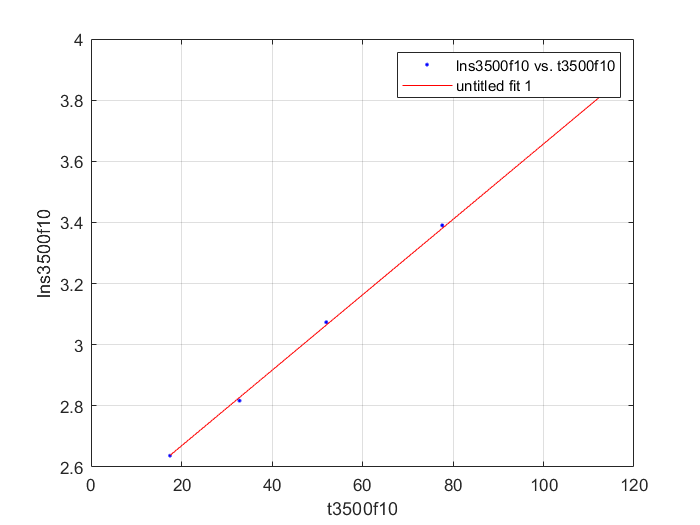

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( t3500f10, lns3500f10 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns3500f10 vs. t3500f10', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel t3500f10
ylabel lns3500f10
grid on



%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01234  (0.0119, 0.01278)
  %     p2 =       2.422  (2.392, 2.453)

%Goodness of fit:
 % SSE: 0.0003478
  %R-square: 0.9996
  %Adjusted R-square: 0.9995
  %RMSE: 0.01077